width=144;
height=226;
imds = imageDatastore('data/Train_Data/Originals/');
inputSize = [height width];
imds.ReadFcn = @(loc)imresize(imread(loc),inputSize);
imagesCellArray = imds.readall();
numImages = numel( imagesCellArray );
[h, w, c] = size( imagesCellArray{1} );
XTrain = zeros( h, w, c, numImages );

for i=1:numImages
XTrain(:,:,:,i) = im2double( imagesCellArray{i} );
end
training_data = [];
training_labels = readtable('data/Train_Data/Train.csv');
YTrain=table2array(training_labels(:,[2 4 5 8 9 10 13 14]));
classNames1 = categories(categorical(YTrain(:,1)));
classNames2 = categories(categorical(YTrain(:,2)));
classNames3 = categories(categorical(YTrain(:,3)));
classNames4 = categories(categorical(YTrain(:,4)));
classNames5 = categories(categorical(YTrain(:,5)));
classNames6 = categories(categorical(YTrain(:,6)));
classNames7 = categories(categorical(YTrain(:,7)));
classNames8 = categories(categorical(YTrain(:,8)));
YTrain= categorical(YTrain);
numObservations = numel(YTrain);

imds = imageDatastore('data/Test_Data/Originals/');
inputSize = [height width];
imds.ReadFcn = @(loc)imresize(imread(loc),inputSize);
imagesCellArray = imds.readall();
numImages = numel( imagesCellArray );
[h, w, c] = size( imagesCellArray{1} );
XTest = zeros( h, w, c, numImages );

for i=1:numImages
XTest(:,:,:,i) = im2double( imagesCellArray{i} );
end
testing_data = [];
testing_labels = readtable('data/Test_Data/Test.csv');
YTest=table2array(testing_labels(:,[2 4 5 8 9 10 13 14]));
YTestD=YTest;
YTest = categorical(YTest);



## Our Network

embeddingSize = 64;
vgg = vgglgraph([height width 3], embeddingSize, [16 32], [256], "none");
vgg = vgg.replaceLayer('input', imageInputLayer([height width 3], 'Normalization', 'None', 'Name', 'input'));
disp(vgg.Layers)

  18×1 Layer array with layers:

     1   'input'               Image Input           226×144×3 images
     2   'convblock_1_C1'      Convolution           16 7×7 convolutions with stride [1  1] and padding 'same'
     3   'convblock_1_relu1'   ReLU                  ReLU
     4   'convblock_1_C2'      Convolution           16 5×5 convolutions with stride [1  1] and padding 'same'
     5   'convblock_1_BN1'     Batch Normalization   Batch normalization
     6   'convblock_1_relu2'   ReLU                  ReLU
     7   'convblock_1_Pool'    Max Pooling           2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     8   'convblock_2_C1'      Convolution           32 7×7 convolutions with stride [1  1] and padding 'same'
     9   'convblock_2_relu1'   ReLU                  ReLU
    10   'convblock_2_C2'      Convolution           32 5×5 convolutions with stride [1  1] and padding 'same'
    11   'convbl

dlnet = dlnetwork(vgg);
genderW=dlarray(0.01*randn(3,embeddingSize));
genderB=dlarray(0.01*randn(1,3));

torsoTypeW=dlarray(0.01*randn(2,embeddingSize));
torsoTypeB=dlarray(0.01*randn(1,2));

torsoColorW=dlarray(0.01*randn(12,embeddingSize));
torsoColorB=dlarray(0.01*randn(1,12));

torsoTextureW=dlarray(0.01*randn(9,embeddingSize));
torsoTextureB=dlarray(0.01*randn(1,9));

legTypeW=dlarray(0.01*randn(2,embeddingSize));
legTypeB=dlarray(0.01*randn(1,2));

legColorW=dlarray(0.01*randn(11,embeddingSize));
legColorB=dlarray(0.01*randn(1,11));

legTextureW=dlarray(0.01*randn(8,embeddingSize));
legTextureB=dlarray(0.01*randn(1,8));

luggageW=dlarray(0.01*randn(2,embeddingSize));
luggageB=dlarray(0.01*randn(1,2));



Pack this all into a struct to keep it together.

outParams = struct(...
    "genderW",genderW,...
    "genderB",genderB,...
    "torsoTypeW",torsoTypeW,...
    "torsoTypeB",torsoTypeB,...
    "torsoColorW",torsoColorW,...
    "torsoColorB",torsoColorB,...
    "torsoTextureW",torsoTextureW,...
    "torsoTextureB",torsoTextureB,...
    "legTypeW",legTypeW,...
    "legTypeB",legTypeB,...
    "legColorW",legColorW,...
    "legColorB",legColorB,...
    "legTextureW",legTextureW,...
    "legTextureB",legTextureB,...
    "luggageW",luggageW,...
    "luggageB",luggageB);

Setup the data holding training information

learningRate = 1e-3;
trailingAvgSubnet = [];
trailingAvgSqSubnet = [];
trailingAvgParams = [];
trailingAvgSqParams = [];
gradDecay = 0.9;
gradDecaySq = 0.99;
executionEnvironment = "auto";

And our plot setup

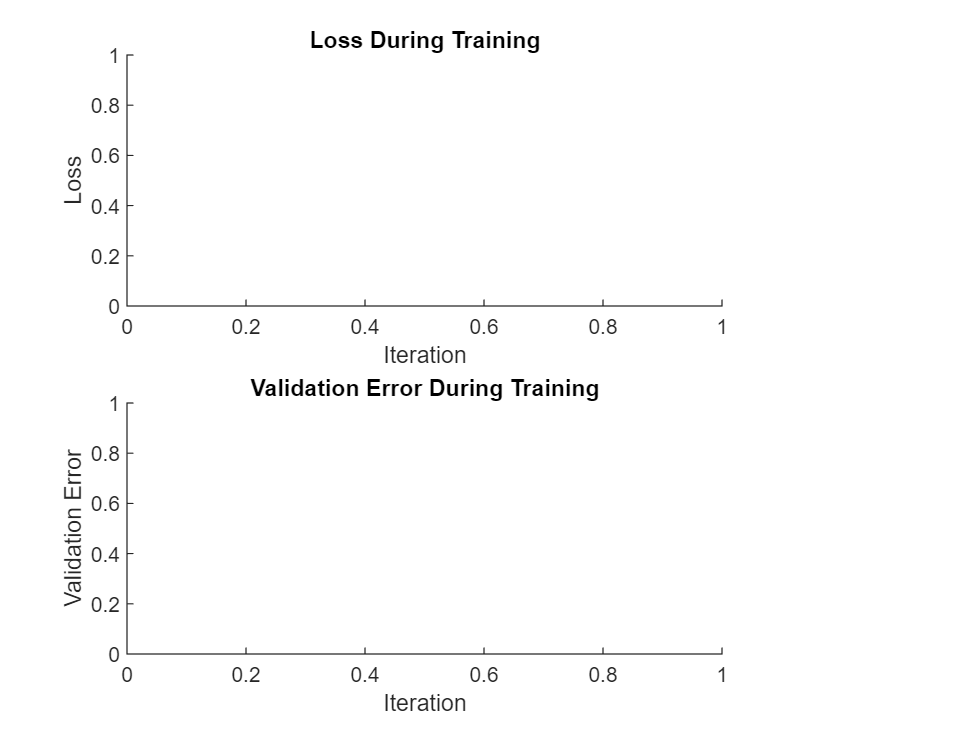

plots = "training-progress";
plotRatio = 16/9;

if plots == "training-progress"
    figure

    trainingPlot = subplot(2,1,1);
    trainingPlot.Position(3) = plotRatio*trainingPlot.Position(4);
    trainingPlot.Visible = 'on';    
    trainingPlotAxes = gca;    
    lineLossTrain = animatedline(trainingPlotAxes, 'Color', 'k');
    lineLoss_gender_Train = animatedline(trainingPlotAxes, 'Color', 'r');
    lineLoss_torso_type_Train = animatedline(trainingPlotAxes, 'Color', 'bl');
    lineLoss_torso_color_Train = animatedline(trainingPlotAxes, 'Color', 'b');
    lineLoss_torso_texture_Train = animatedline(trainingPlotAxes, 'Color', 'c');
    lineLoss_leg_type_Train = animatedline(trainingPlotAxes, 'Color', 'm');
    lineLoss_leg_color_Train = animatedline(trainingPlotAxes, 'Color', 'y');
    lineLoss_leg_texture_Train = animatedline(trainingPlotAxes, 'Color', 'n');
    lineLoss_luggage_Train = animatedline(trainingPlotAxes, 'Color', 'g');
    xlabel(trainingPlotAxes,"Iteration")
    ylabel(trainingPlotAxes,"Loss")
    title(trainingPlotAxes,"Loss During Training")

    validationPlot = subplot(2,1,2);
    validationPlot.Position(3) = plotRatio*validationPlot.Position(4);
    validationPlot.Visible = 'on';    
    validationPlotAxes = gca;    
    lineVal_gender = animatedline(validationPlotAxes, 'Color', 'r');
    lineVal_torso_type = animatedline(validationPlotAxes, 'Color', 'bl');
    lineVal_torso_color = animatedline(validationPlotAxes, 'Color', 'b');
    lineVal_torso_texture = animatedline(validationPlotAxes, 'Color', 'c');
    lineVal_leg_type = animatedline(validationPlotAxes, 'Color', 'm');
    lineVal_leg_color = animatedline(validationPlotAxes, 'Color', 'y');
    lineVal_leg_texture = animatedline(validationPlotAxes, 'Color', 'n');
    lineVal_luggage = animatedline(validationPlotAxes, 'Color', 'g');
    xlabel(validationPlotAxes,"Iteration")
    ylabel(validationPlotAxes,"Validation Error")
    title(validationPlotAxes,"Validation Error During Training")
end

## Training the Network

First up we'll set various training parameters that we haven't already captured

batch_size = 64;
num_epochs = 10;
batches_per_epoch = int32(floor(length(YTrain)/batch_size));
current_idx = 1;
numGender = 3;
numTorsoType = 2;
numTorsoColor = 12;
numTorsoTexture = 9;
numLegType = 2;
numLegColor = 11;
numLegTexture = 8;
numLuggage = 2;
iteration = 1;
validationfrequency = 30;

Now w're onto the main loop

for epoch = 1:num_epochs    

At the start of each epoch, we'll shuffle the data

    shuff_idx = randperm(length(YTrain), length(YTrain));
    XTrain = XTrain(:,:,:,shuff_idx);
    YTrain = YTrain(shuff_idx,:); 
    current_idx = 1;
    
    for batch = 1:batches_per_epoch      

Exttract out our next batch of data, and if we can push it to a GPU

        dlX = dlarray(single(XTrain(:,:,:,current_idx:(current_idx + batch_size))), 'SSCB');     
        dlY1 = zeros(numGender, batch_size+1, 'single');
        for c = 1:numGender
            dlY1(c,YTrain(current_idx:(current_idx + batch_size), 1)==classNames1(c)) = 1;
        end
        dlY2 = zeros(numTorsoType, batch_size+1, 'single');
        for c = 1:numTorsoType
            dlY2(c,YTrain(current_idx:(current_idx + batch_size), 2)==classNames2(c)) = 1;
        end
        dlY3 = zeros(numTorsoColor, batch_size+1, 'single');
        for c = 1:numTorsoColor
            dlY3(c,YTrain(current_idx:(current_idx + batch_size), 3)==classNames3(c)) = 1;
        end
        dlY4 = zeros(numTorsoTexture, batch_size+1, 'single');
        for c = 1:numTorsoTexture
            dlY4(c,YTrain(current_idx:(current_idx + batch_size), 4)==classNames4(c)) = 1;
        end
        dlY5 = zeros(numLegType, batch_size+1, 'single');
        for c = 1:numLegType
            dlY5(c,YTrain(current_idx:(current_idx + batch_size), 5)==classNames5(c)) = 1;
        end
        dlY6 = zeros(numLegColor, batch_size+1, 'single');
        for c = 1:numLegColor
            dlY6(c,YTrain(current_idx:(current_idx + batch_size), 6)==classNames6(c)) = 1;
        end
        dlY7 = zeros(numLegTexture, batch_size+1, 'single');
        for c = 1:numLegTexture
            dlY7(c,YTrain(current_idx:(current_idx + batch_size), 7)==classNames7(c)) = 1;
        end
        dlY8 = zeros(numLuggage, batch_size+1, 'single');
        for c = 1:numLuggage
            dlY8(c,YTrain(current_idx:(current_idx + batch_size), 8)==classNames8(c)) = 1;
        end

        if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
            dlX = gpuArray(dlX);
        end           

We'll use dfeval and a modelGradients function that's below to train the network

        [gradientsSubnet, gradientsParams, loss_gender, loss_torso_type, loss_torso_color, loss_torso_texture, loss_leg_type, loss_leg_color, loss_leg_texture, loss_luggage] = dlfeval(@modelGradients, dlnet, outParams, dlX, dlY1, dlY2, dlY3, dlY4, dlY5, dlY6, dlY7, dlY8, 100/3, 100/2, 100/12, 100/9, 100/2, 100/11, 100/8, 100/2);

And then do our gradient updates for the two parts of the network

        [dlnet,trailingAvgSubnet,trailingAvgSqSubnet] = ...
            adamupdate(dlnet,gradientsSubnet, ...
            trailingAvgSubnet,trailingAvgSqSubnet,iteration,learningRate,gradDecay,gradDecaySq);

        [outParams,trailingAvgParams,trailingAvgSqParams] = ...
            adamupdate(outParams,gradientsParams, ...
            trailingAvgParams,trailingAvgSqParams,iteration,learningRate,gradDecay,gradDecaySq);

Finally we can plot some stuff

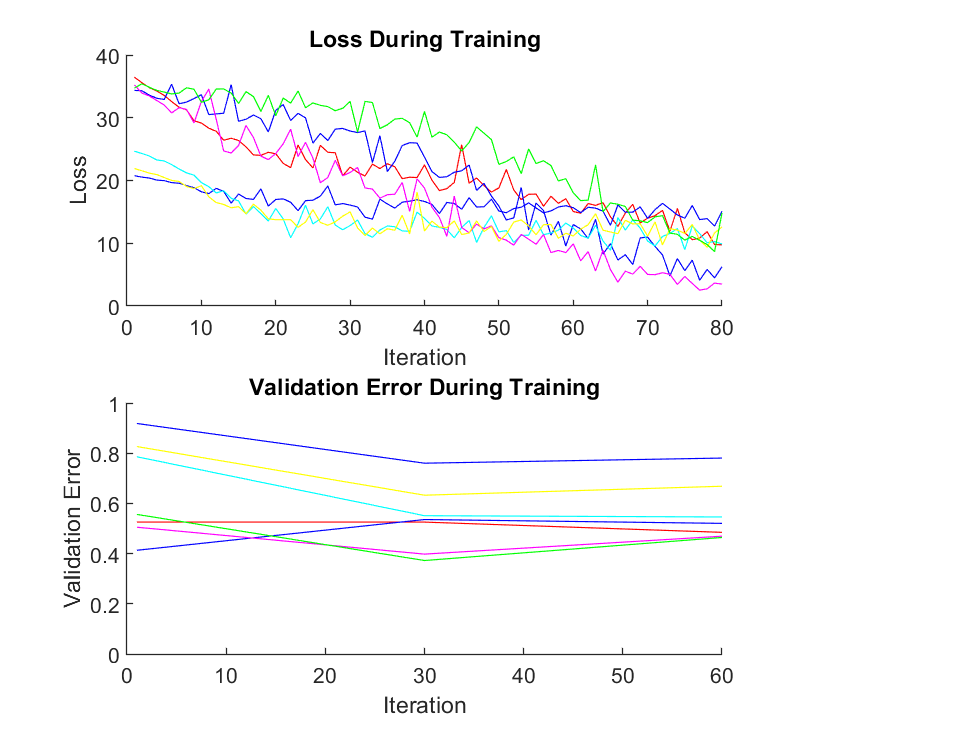

        if plots == "training-progress"

            addpoints(lineLoss_gender_Train, iteration, double(gather(extractdata(loss_gender))));
            addpoints(lineLoss_torso_type_Train, iteration, double(gather(extractdata(loss_torso_type))));
            addpoints(lineLoss_torso_color_Train, iteration, double(gather(extractdata(loss_torso_color))));
            addpoints(lineLoss_torso_texture_Train, iteration, double(gather(extractdata(loss_torso_texture))));
            addpoints(lineLoss_leg_type_Train, iteration, double(gather(extractdata(loss_leg_type))));
            addpoints(lineLoss_leg_color_Train, iteration, double(gather(extractdata(loss_leg_color))));
            addpoints(lineLoss_leg_texture_Train, iteration, double(gather(extractdata(loss_leg_texture))));
            addpoints(lineLoss_luggage_Train, iteration, double(gather(extractdata(loss_luggage))));
        
            if ((mod(iteration, validationfrequency) == 0) || (iteration == 1))
                [gender_error, torso_type_error, torso_color_error, torso_texture_error, leg_type_error, leg_color_error, leg_texture_error, luggage_error] = validationError(executionEnvironment, dlnet, outParams, classNames1, classNames2, classNames3, classNames4, classNames5, classNames6, classNames7, classNames8, XTest, YTest);
                addpoints(lineVal_gender, iteration, gender_error);
                addpoints(lineVal_torso_type, iteration, torso_type_error);
                addpoints(lineVal_torso_color, iteration, torso_color_error);
                addpoints(lineVal_torso_texture, iteration, torso_texture_error);
                addpoints(lineVal_leg_type, iteration, leg_type_error);
                addpoints(lineVal_leg_color, iteration, leg_color_error);
                addpoints(lineVal_leg_texture, iteration, leg_texture_error);
                addpoints(lineVal_luggage, iteration, luggage_error);
            end
            drawnow
        end        

        current_idx = current_idx + batch_size;
        iteration = iteration + 1;
        
    end
end

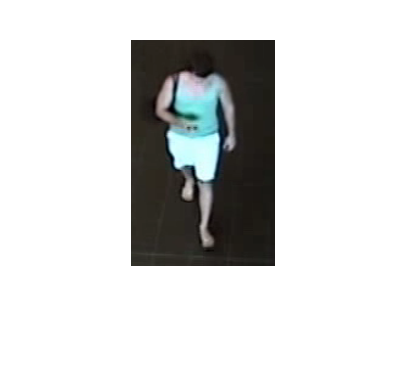

figure
pic=XTest(:,:,:,1);
imshow(pic)

[gender, torso_type, torso_color, torso_texture, leg_type, leg_color, leg_texture, luggage] = predictOne(dlnet, outParams, pic, classNames1, classNames2, classNames3, classNames4, classNames5, classNames6, classNames7, classNames8)

gender = 1×1 cell array
    {'1'}


torso_type = 1×1 cell array
    {'1'}


torso_color = 1×1 cell array
    {'9'}


torso_texture = 1×1 cell array
    {'3'}


leg_type = 1×1 cell array
    {'1'}


leg_color = 1×1 cell array
    {'1'}


leg_texture = 1×1 cell array
    {'3'}


luggage = 1×1 cell array
    {'0'}


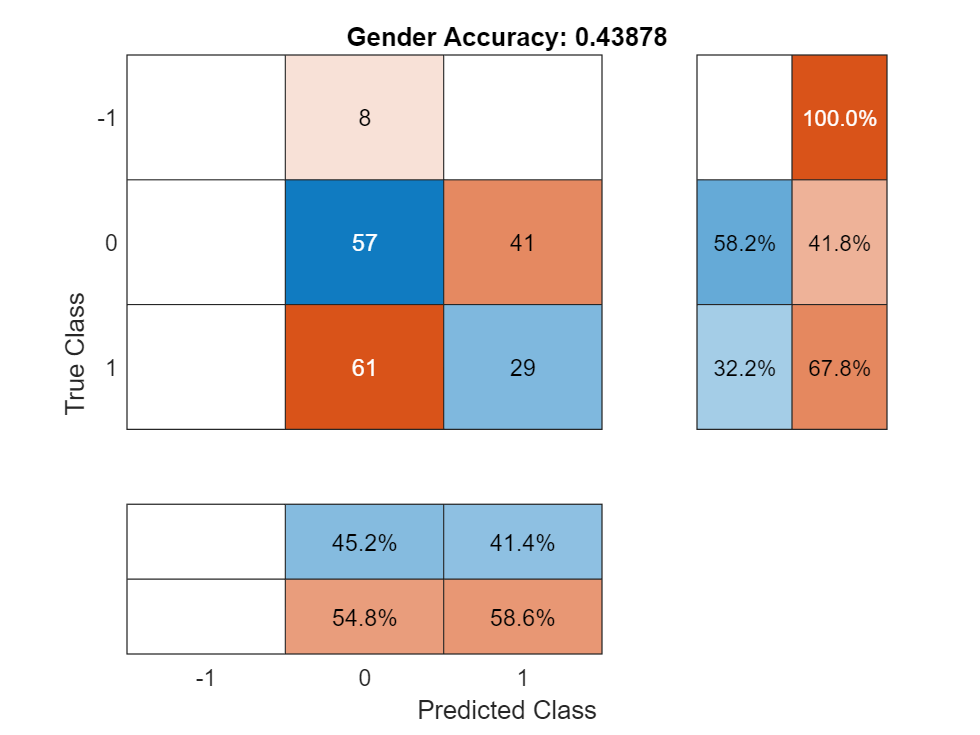

testPred=predictAll(dlnet, outParams, XTest, classNames1, classNames2, classNames3, classNames4, classNames5, classNames6, classNames7, classNames8);
testPredD=zeros(size(testPred,1),size(testPred,2));
testPredD=str2double(testPred);
figure
confusionchart( YTestD(:,1), testPredD(:,1), 'RowSummary','row-normalized','ColumnSummary','column-normalized');
title("Gender Accuracy: " + string(sum(testPredD(:,1) == YTestD(:,1))/length(testPredD)))

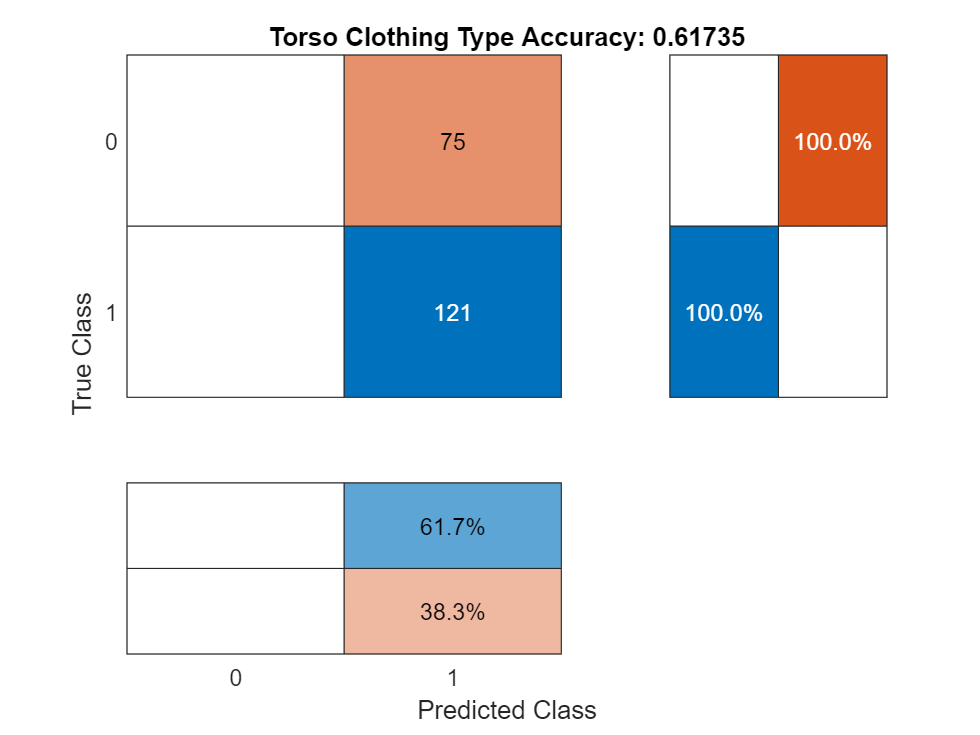

confusionchart(  YTestD(:,2),testPredD(:,2),'RowSummary','row-normalized','ColumnSummary','column-normalized');
title("Torso Clothing Type Accuracy: " + string(sum(testPredD(:,2) == YTestD(:,2))/length(testPredD)))

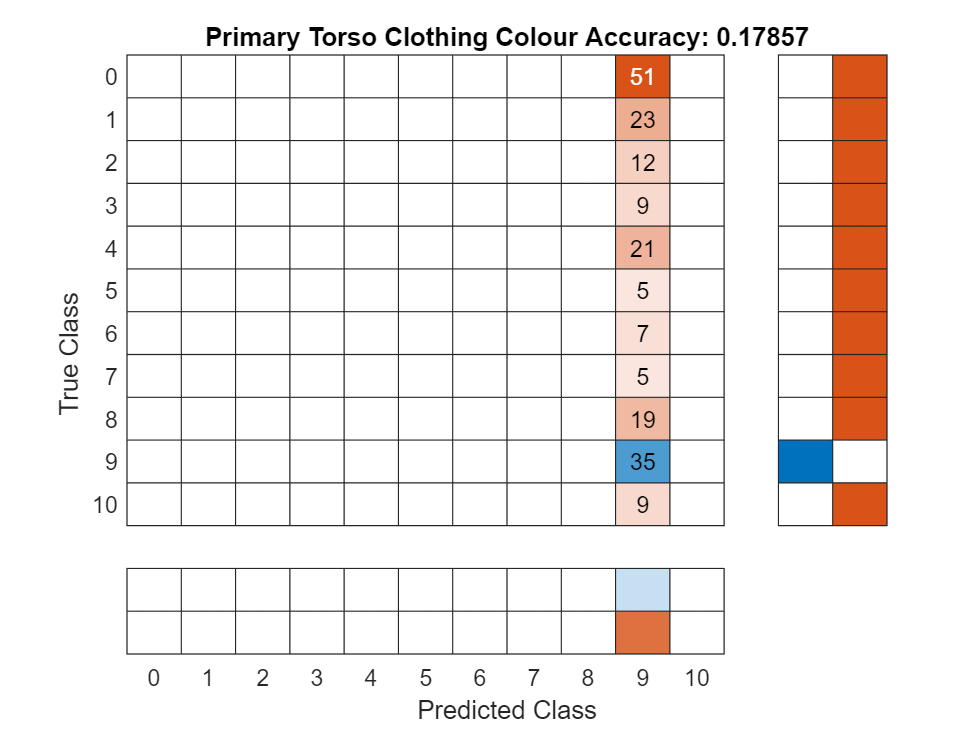

confusionchart(  YTestD(:,3),testPredD(:,3),'RowSummary','row-normalized','ColumnSummary','column-normalized');
title("Primary Torso Clothing Colour Accuracy: " + string(sum(testPredD(:,3) == YTestD(:,3))/length(testPredD)))

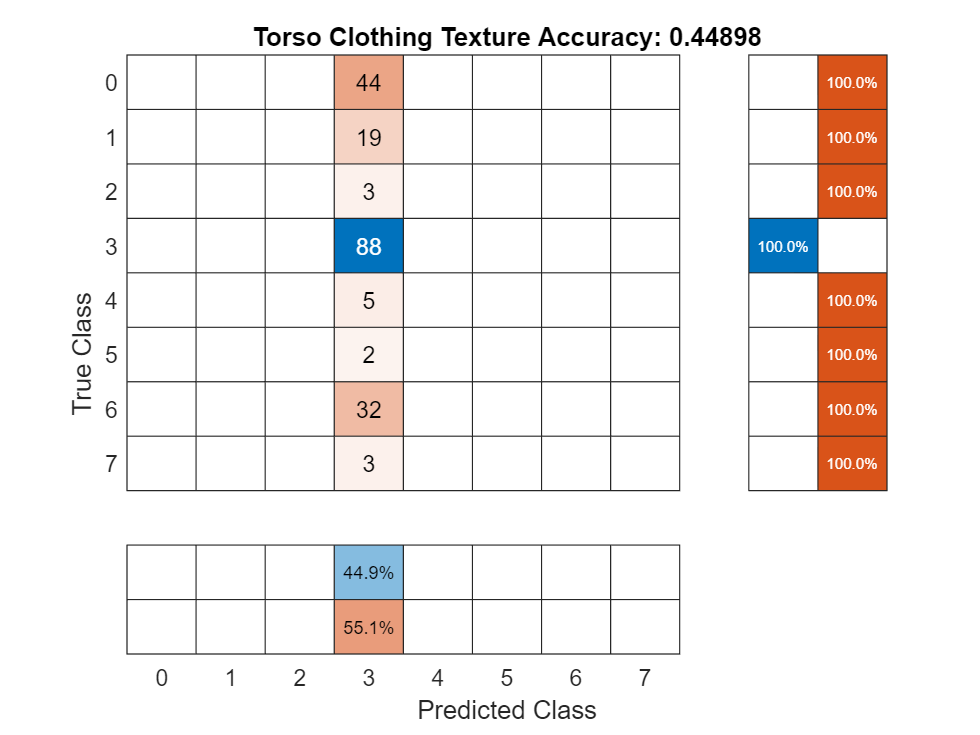

confusionchart(  YTestD(:,4),testPredD(:,4),'RowSummary','row-normalized','ColumnSummary','column-normalized');
title("Torso Clothing Texture Accuracy: " + string(sum(testPredD(:,4) == YTestD(:,4))/length(testPredD)))

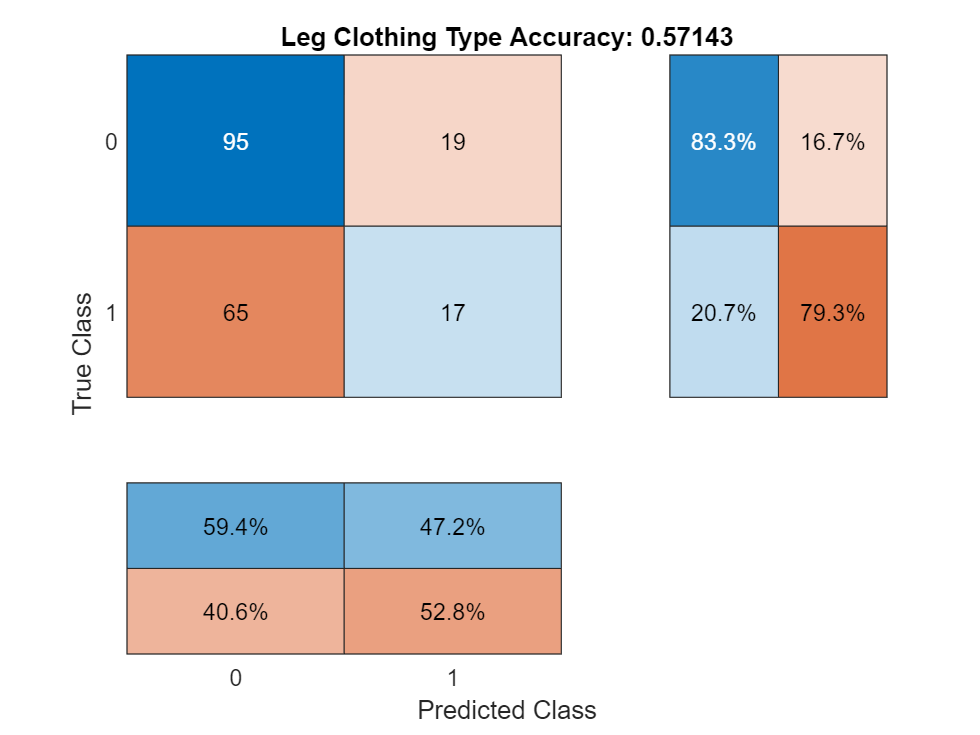

confusionchart(  YTestD(:,5),testPredD(:,5),'RowSummary','row-normalized','ColumnSummary','column-normalized');
title("Leg Clothing Type Accuracy: " + string(sum(testPredD(:,5) == YTestD(:,5))/length(testPredD)))

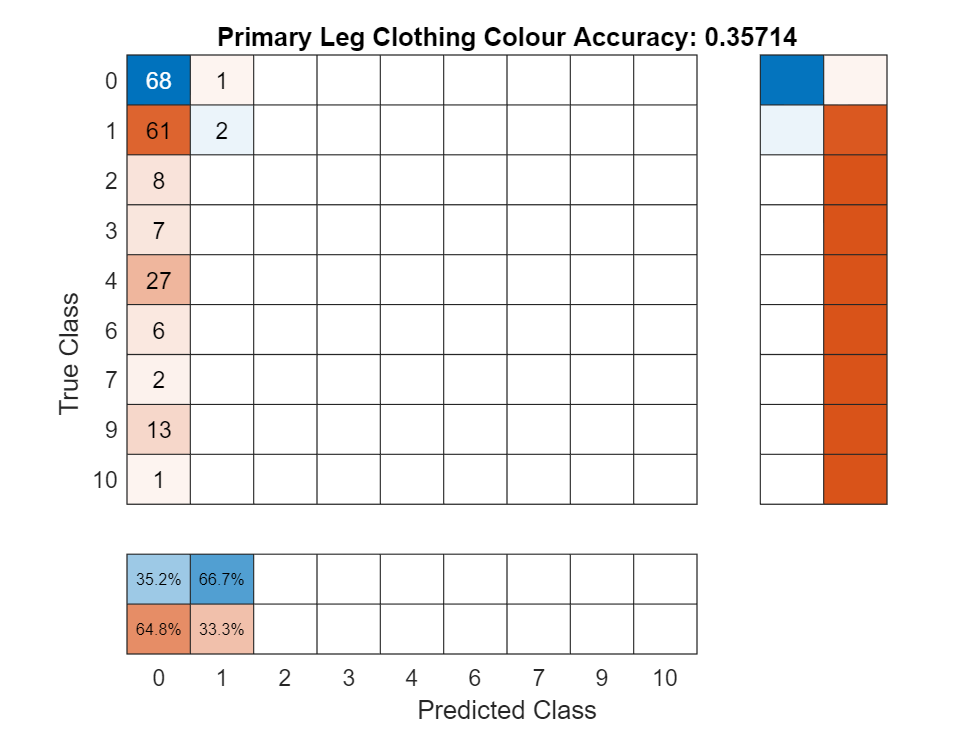

confusionchart(  YTestD(:,6),testPredD(:,6),'RowSummary','row-normalized','ColumnSummary','column-normalized');
title("Primary Leg Clothing Colour Accuracy: " + string(sum(testPredD(:,6) == YTestD(:,6))/length(testPredD)))

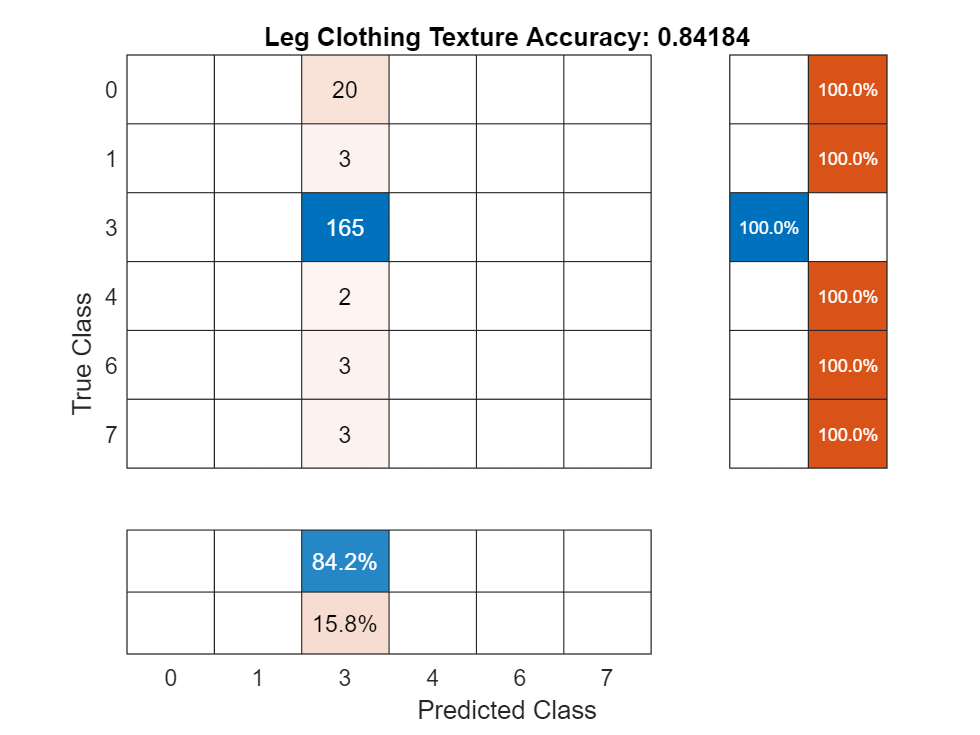

confusionchart(  YTestD(:,7),testPredD(:,7),'RowSummary','row-normalized','ColumnSummary','column-normalized');
title("Leg Clothing Texture Accuracy: " + string(sum(testPredD(:,7) == YTestD(:,7))/length(testPredD)))

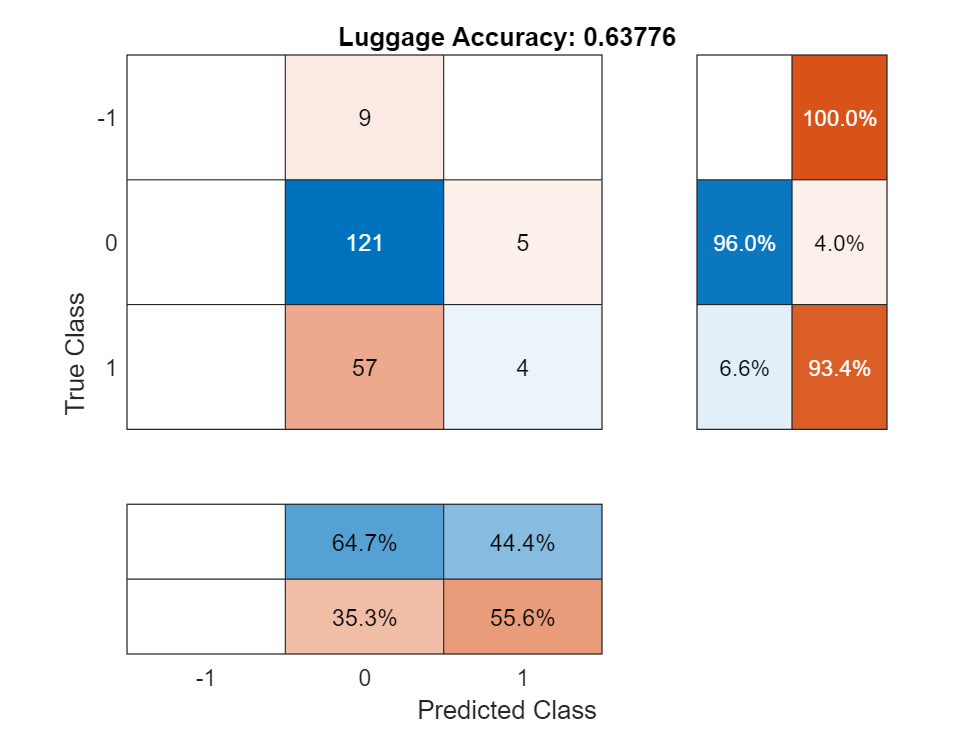

confusionchart(  YTestD(:,8),testPredD(:,8),'RowSummary','row-normalized','ColumnSummary','column-normalized');
title("Luggage Accuracy: " + string(sum(testPredD(:,8) == YTestD(:,8))/length(testPredD)))

## Helper Functions

% compute a forward pass through the network, return the outputs from the
% two heads

function [Y1, Y2, Y3, Y4, Y5, Y6, Y7, Y8] = forwardPass(dlnet, outParams, dlX)


    F = forward(dlnet, dlX);
    F = relu(F);
    

    Y1 = fullyconnect(F, outParams.genderW, outParams.genderB);
    Y1 = softmax(Y1);
    Y2 = fullyconnect(F, outParams.torsoTypeW, outParams.torsoTypeB);
    Y2 = softmax(Y2);
    Y3 = fullyconnect(F, outParams.torsoColorW, outParams.torsoColorB);
    Y3 = softmax(Y3);
    Y4 = fullyconnect(F, outParams.torsoTextureW, outParams.torsoTextureB);
    Y4 = softmax(Y4);
    Y5 = fullyconnect(F, outParams.legTypeW, outParams.legTypeB);
    Y5 = softmax(Y5);
    Y6 = fullyconnect(F, outParams.legColorW, outParams.legColorB);
    Y6 = softmax(Y6);
    Y7 = fullyconnect(F, outParams.legTextureW, outParams.legTextureB);
    Y7 = softmax(Y7);
    Y8 = fullyconnect(F, outParams.luggageW, outParams.luggageB);
    Y8 = softmax(Y8);
end
function [Y1, Y2, Y3, Y4, Y5, Y6, Y7, Y8] = predictOne(dlnet, outParams, pic, classNames1, classNames2, classNames3, classNames4, classNames5, classNames6, classNames7, classNames8)

    pic = dlarray(single(pic),'SSCB');

    F = dlnet.predict(pic);
    F = leakyrelu(F);

    
    % forward pass through the classification head, softmax activation here
    Y1 = fullyconnect(F, outParams.genderW, outParams.genderB);
    Y1 = softmax(Y1);
    Y2 = fullyconnect(F, outParams.torsoTypeW, outParams.torsoTypeB);
    Y2 = softmax(Y2);
    Y3 = fullyconnect(F, outParams.torsoColorW, outParams.torsoColorB);
    Y3 = softmax(Y3);
    Y4 = fullyconnect(F, outParams.torsoTextureW, outParams.torsoTextureB);
    Y4 = softmax(Y4);
    Y5 = fullyconnect(F, outParams.legTypeW, outParams.legTypeB);
    Y5 = softmax(Y5);
    Y6 = fullyconnect(F, outParams.legColorW, outParams.legColorB);
    Y6 = softmax(Y6);
    Y7 = fullyconnect(F, outParams.legTextureW, outParams.legTextureB);
    Y7 = softmax(Y7);
    Y8 = fullyconnect(F, outParams.luggageW, outParams.luggageB);
    Y8 = softmax(Y8);
    
    [~, pred] = max(extractdata(Y1), [], 1);
    Y1 = classNames1(pred);
    
    [~, pred] = max(extractdata(Y2), [], 1);
    Y2 = classNames2(pred);
    

    [~, pred] = max(extractdata(Y3), [], 1);
    Y3 = classNames3(pred);
    
    [~, pred] = max(extractdata(Y4), [], 1);
    Y4 = classNames4(pred);
    
    [~, pred] = max(extractdata(Y5), [], 1);
    Y5 = classNames5(pred);
    
    [~, pred] = max(extractdata(Y6), [], 1);
    Y6 = classNames6(pred);
    
    [~, pred] = max(extractdata(Y7), [], 1);
    Y7 = classNames7(pred);
    
    [~, pred] = max(extractdata(Y8), [], 1);
    Y8 = classNames8(pred);
end
function [predictions] = predictAll(dlnet, outParams, pic, classNames1, classNames2, classNames3, classNames4, classNames5, classNames6, classNames7, classNames8)

    pic = dlarray(single(pic),'SSCB');

    F = dlnet.predict(pic);
    F = leakyrelu(F);
    
    % forward pass through the classification head, softmax activation here
    % as we want a class output
    Y1 = fullyconnect(F, outParams.genderW, outParams.genderB);
    Y1 = softmax(Y1);
    Y2 = fullyconnect(F, outParams.torsoTypeW, outParams.torsoTypeB);
    Y2 = softmax(Y2);
    Y3 = fullyconnect(F, outParams.torsoColorW, outParams.torsoColorB);
    Y3 = softmax(Y3);
    Y4 = fullyconnect(F, outParams.torsoTextureW, outParams.torsoTextureB);
    Y4 = softmax(Y4);
    Y5 = fullyconnect(F, outParams.legTypeW, outParams.legTypeB);
    Y5 = softmax(Y5);
    Y6 = fullyconnect(F, outParams.legColorW, outParams.legColorB);
    Y6 = softmax(Y6);
    Y7 = fullyconnect(F, outParams.legTextureW, outParams.legTextureB);
    Y7 = softmax(Y7);
    Y8 = fullyconnect(F, outParams.luggageW, outParams.luggageB);
    Y8 = softmax(Y8);
    
    [~, pred] = max(extractdata(Y1), [], 1);
    Y1 = classNames1(pred);
    
    [~, pred] = max(extractdata(Y2), [], 1);
    Y2 = classNames2(pred);
    
    [~, pred] = max(extractdata(Y3), [], 1);
    Y3 = classNames3(pred);
    
    [~, pred] = max(extractdata(Y4), [], 1);
    Y4 = classNames4(pred);
    
    [~, pred] = max(extractdata(Y5), [], 1);
    Y5 = classNames5(pred);
    
    [~, pred] = max(extractdata(Y6), [], 1);
    Y6 = classNames6(pred);
    
    [~, pred] = max(extractdata(Y7), [], 1);
    Y7 = classNames7(pred);
    
    [~, pred] = max(extractdata(Y8), [], 1);
    Y8 = classNames8(pred);
    predictions=[Y1, Y2, Y3, Y4, Y5, Y6, Y7, Y8];
end
% compute the validation error of the network
function [gender_error, torso_type_error, torso_color_error, torso_texture_error, leg_type_error, leg_color_error, leg_texture_error, luggage_error] = validationError(executionEnvironment, dlnet, outParams, classNames1, classNames2, classNames3, classNames4, classNames5, classNames6, classNames7, classNames8, XTest, YTest) 

   

    % we'll pump the entire validation set through
    dlX = dlarray(single(XTest),'SSCB');
    if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
        dlX = gpuArray(dlX);
    end       

    % forward pass through the network
    [dlY1, dlY2, dlY3, dlY4, dlY5, dlY6, dlY7, dlY8] = forwardPass(dlnet, outParams, dlX);

    % compute classification error. 

    [~, pred] = max(extractdata(dlY1), [], 1);
    labelsPred = classNames1(pred);
    gender_error = 1.0 - mean(labelsPred==YTest(:,1));
    %(sum(labelsPred==YTest(:,1)))/length(labelsPred)
    
    [~, pred] = max(extractdata(dlY2), [], 1);
    labelsPred = classNames2(pred);
    torso_type_error = 1.0 - mean(labelsPred==YTest(:,2));
    %(sum(labelsPred==YTest(:,2)))/length(labelsPred)
    

    [~, pred] = max(extractdata(dlY3), [], 1);
    labelsPred = classNames3(pred);
    torso_color_error = 1.0 - mean(labelsPred==YTest(:,3));
    %(sum(labelsPred==YTest(:,3)))/length(labelsPred)
    
    [~, pred] = max(extractdata(dlY4), [], 1);
    labelsPred = classNames4(pred);
    torso_texture_error = 1.0 - mean(labelsPred==YTest(:,4));
    %(sum(labelsPred==YTest(:,4)))/length(labelsPred)
    
    [~, pred] = max(extractdata(dlY5), [], 1);
    labelsPred = classNames5(pred);
    leg_type_error = 1.0 - mean(labelsPred==YTest(:,5));
    %(sum(labelsPred==YTest(:,5)))/length(labelsPred)
    
    [~, pred] = max(extractdata(dlY6), [], 1);
    labelsPred = classNames6(pred);
    leg_color_error = 1.0 - mean(labelsPred==YTest(:,6));
    %(sum(labelsPred==YTest(:,6)))/length(labelsPred)
    
    [~, pred] = max(extractdata(dlY7), [], 1);
    labelsPred = classNames7(pred);
    leg_texture_error = 1.0 - mean(labelsPred==YTest(:,7));
    %(sum(labelsPred==YTest(:,7)))/length(labelsPred)
    
    [~, pred] = max(extractdata(dlY8), [], 1);
    labelsPred = classNames8(pred);
    luggage_error = 1.0 - mean(labelsPred==YTest(:,8));
    %(sum(labelsPred==YTest(:,8)))/length(labelsPred)
end

% model gradients, get the gradients through the network so we can upadte
% the model
function [gradientsSubnet, gradientsParams, loss_gender, loss_torso_type, loss_torso_color, loss_torso_texture, loss_leg_type, loss_leg_color, loss_leg_texture, loss_luggage] = modelGradients(dlnet, outParams, dlX, dlY1, dlY2, dlY3, dlY4, dlY5, dlY6, dlY7, dlY8, w1, w2, w3, w4, w5, w6, w7, w8)

    % forward pass through the network
    [Y1, Y2, Y3, Y4, Y5, Y6, Y7, Y8] = forwardPass(dlnet,outParams,dlX);

    % get our losses, note that we apply the loss weights here
    loss_gender = crossentropy(Y1, dlY1)*w1;
    loss_torso_type = crossentropy(Y2, dlY2)*w2;
    loss_torso_color = crossentropy(Y3, dlY3)*w3;
    loss_torso_texture = crossentropy(Y4, dlY4)*w4;
    loss_leg_type = crossentropy(Y5, dlY5)*w5;
    loss_leg_color = crossentropy(Y6, dlY6)*w6;
    loss_leg_texture = crossentropy(Y7, dlY7)*w7;
    loss_luggage = crossentropy(Y8, dlY8)*w8;

    % compute our gradients using the sum of the losses
    [gradientsSubnet,gradientsParams] = dlgradient(loss_gender + loss_torso_type + loss_torso_color + loss_torso_texture + loss_leg_type + loss_leg_color + loss_leg_texture + loss_luggage, dlnet.Learnables, outParams);
end